# ECM307-G01T02L03D - Atividade T3

%% Atividade T3 - Análise de Vogais
%% Luis Guilherme de Souza Munhoz RA: 20.01937-8 Lab: 3

## Boas Práticas

clc;                                       % limpa a tela
clear all;                                 % limpar as variáveis
close all;                                 % fecha as figuras abertas

## baixando arquivo de voz e plotando gráficos

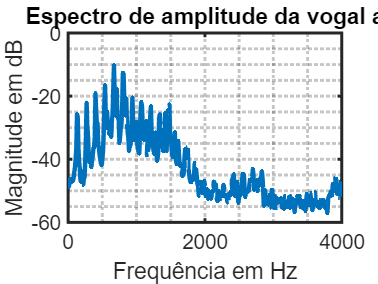

load("Voz.mat")
figure(1)
plot(frequencia,Y0)
title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

%%% modifica parâmteros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

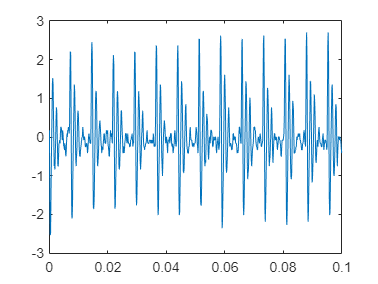



figure(2)
plot(t,Vp)

## calculando amostragem

fs = length(Vp)/0.1

fs = 8000

Ts = 1/fs

Ts = 1.2500e-04

## analise de fourier

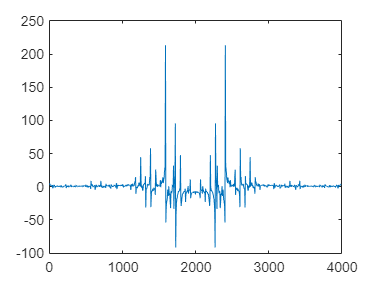

FFTVp = fftshift(fft(Vp));
frequencia2 = linspace(frequencia(1), frequencia(400), 800);
figure(3)
plot(frequencia2, FFTVp)

## Laplace

% achar sigma e omega de laplace


$$\begin{array}{l}
s=\sigma +j\omega \to e^{-\left(\sigma +j\omega \;\right)} \to e^{-\sigma \;t} e^{-j\omega t} \\
e^{-\sigma } e^{-j\omega t} \\
e^{-\sigma t} \left(\cos \left(\omega t\right)+\mathrm{jsin}\left(\omega t\right)\right)+\\
e^{-\sigma t} \left(\cos \left(\omega t\right)-\mathrm{jsin}\left(\omega t\right)\right)=\\
2e^{-\sigma t} \cos \left(\omega t\right)
\end{array}$$


ti = 0.00112641;        % periodo inicial
t_f = 0.0953692;        % periodo final
T = (t_f - ti)/13;       % 13 = número de periodos
f = 1/T;
w = 2*pi*f

w = 866.7126

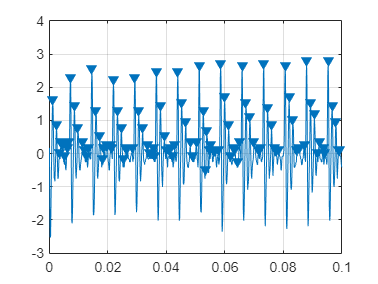


figure(3)

findpeaks(Vp,t,'MinPeakDistance',0.001);


[vt,tp]=findpeaks(Vp,t,"MinPeakDistance",0.001);

sigma =mean(diff(tp));

exponencial = exp(-sigma*t)

exponencial =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


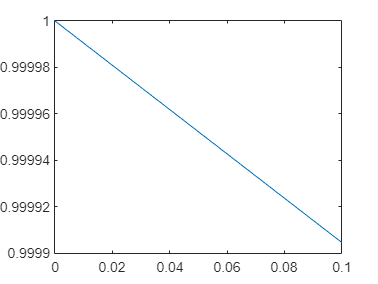

plot(t,exponencial)